clear all
close all

%WORKING IN eV

v2=5e+9;
vx=1.8e+13; %18 TeV
M11=1000;
smin=0;
smax=90;
a=1.45e-9;
r1=a;
r2=a;
hxmin=0.01;
hxmax=0.1;

h2eevno=zeros(1,100);
h2euvno=zeros(1,100);
h2etvno=zeros(1,100);
h2uevno=zeros(1,100);
h2uuvno=zeros(1,100);
h2utvno=zeros(1,100);
hx1vno=zeros(1,100);
hx2vno=zeros(1,100);
hx3vno=zeros(1,100);
ssno=zeros(1,100);
m1vno=zeros(1,100);
m2vno=zeros(1,100);
m3vno=zeros(1,100);

h2eevio=zeros(1,100);
h2euvio=zeros(1,100);
h2etvio=zeros(1,100);
h2uevio=zeros(1,100);
h2uuvio=zeros(1,100);
h2utvio=zeros(1,100);
hx1vio=zeros(1,100);
hx2vio=zeros(1,100);
hx3vio=zeros(1,100);
ssio=zeros(1,100);
m1vio=zeros(1,100);
m2vio=zeros(1,100);
m3vio=zeros(1,100);

k=0;
z=0;

Mm=[M11 0 0 ; 0 M11 0 ; 0 0 M11];
tic
for i=1:5000000
    hx1=hxmin+rand*(hxmax-hxmin);
    hx2=hxmin+rand*(hxmax-hxmin);
    hx3=hxmin+rand*(hxmax-hxmin);
    h2ee=rand;
    h2eu=rand;
    h2et=rand;
    h2ue=rand;
    h2uu=rand;
    h2ut=0;
    
    mD=(v2/sqrt(2))*[h2ee h2eu h2et ; h2ue h2uu h2ut ; 0 0 0];
    MD=(vx/sqrt(2))*[hx1 0 0 ; 0 hx2 0 ; 0 0 hx3];
    
    mv=mD'*inv(MD)*Mm*inv(MD')*mD;
    
    
    [v,g]=eig(mv);
    
    eigmass=[abs(g(1,1));abs(g(2,2));abs(g(3,3))];
    mmax=max(eigmass);
    %With this i limit max value of neutrino masses to 0.1
    mmin=min(eigmass);
    if (mmax<0.1)
        
        for q=1:3
            if (eigmass(q)==mmin)
                posmin=q;
            end
            if ((eigmass(q)<mmax) && (eigmass(q)>mmin))
                posmed=q;
            end
            if (eigmass(q)==mmax)
                posmax=q;
            end
        end
        
        s_emu=smin+rand*(smax-smin);
        
        
        Rl=[cos(s_emu*pi/180) sin(s_emu*pi/180) r1 ; -sin(s_emu*pi/180) cos(s_emu*pi/180) r2 ; -r1*cos(s_emu*pi/180)+r2*sin(s_emu*pi/180) -r2*cos(s_emu*pi/180)-r1*sin(s_emu*pi/180) 1];
        Upmns=Rl*v;
        
        %Choose only acceptable values of pmns
         if (abs(Upmns(1,1))<(0.845) && (abs(Upmns(1,1))>(0.801)))
            
            if (abs(Upmns(1,2))<(0.579) && (abs(Upmns(1,2))>(0.513)))
                
                if (abs(Upmns(1,3))<(0.156) && (abs(Upmns(1,3))>(0.143)))
                    
                    if (abs(Upmns(2,1))<(0.507) && (abs(Upmns(2,1))>(0.233)))
                        
                        if (abs(Upmns(2,2))<(0.694) && (abs(Upmns(2,2))>(0.461)))
                            
                            if (abs(Upmns(2,3))<(0.778) && (abs(Upmns(2,3))>(0.631)))
                                
                                if (abs(Upmns(3,1))<(0.526) && (abs(Upmns(3,1))>(0.261)))
                                    
                                    if (abs(Upmns(3,2))<(0.701) && (abs(Upmns(3,2))>(0.471)))
                                        
                                        if (abs(Upmns(3,3))<(0.761) && (abs(Upmns(3,3))>(0.611)))
                                            if ((abs(Upmns(1,posmin))>abs(Upmns(1,posmed)) && (abs(Upmns(1,posmed))>abs(Upmns(1,posmax)))))%choose between NO and IO
                                                k=k+1;
                                                h2eevno(k)=h2ee;
                                                h2euvno(k)=h2eu;
                                                h2etvno(k)=h2et;
                                                h2uevno(k)=h2ue;
                                                h2uuvno(k)=h2uu;
                                                h2utvno(k)=h2ut;
                                                hx1vno(k)=hx1;
                                                hx2vno(k)=hx2;
                                                hx3vno(k)=hx3;
                                                ssno(k)=s_emu;
                                                m1vno(k)=g(1,1);
                                                m2vno(k)=g(2,2);
                                                m3vno(k)=g(3,3);
                                                k
                                                Upmns
                                            end
                            
                                            if ((abs(Upmns(1,posmed))>abs(Upmns(1,posmin))))
                                                z=z+1;
                                                h2eevio(z)=h2ee;
                                                h2euvio(z)=h2eu;
                                                h2etvio(z)=h2et;
                                                h2uevio(z)=h2ue;
                                                h2uuvio(z)=h2uu;
                                                h2utvio(z)=h2ut;
                                                hx1vio(z)=hx1;
                                                hx2vio(z)=hx2;
                                                hx3vio(z)=hx3;
                                                ssio(z)=s_emu;
                                                m1vio(z)=g(1,1);
                                                m2vio(z)=g(2,2);
                                                m3vio(z)=g(3,3);
                                                z
                                                Upmns
                                            end
                                            
                                        end
                                    end
                                end
                            end
                        end
                    end
                end
            end
        end
    end
    
end

z = 1

Upmns =    -0.8278   -0.5417    0.1460
   -0.4465    0.4785   -0.7561
   -0.3397    0.6911    0.6379


z = 2

Upmns =     0.8223    0.5473   -0.1558
    0.2839   -0.6319   -0.7212
    0.4932   -0.5488    0.6750


z = 3

Upmns =    -0.8226   -0.5481    0.1516
   -0.4712    0.5076   -0.7213
   -0.3184    0.6648    0.6758


z = 4

Upmns =    -0.8042   -0.5737    0.1554
   -0.5066    0.5249   -0.6840
   -0.3108    0.6288    0.7128


z = 5

Upmns =     0.8122    0.5635   -0.1509
    0.3070   -0.6328   -0.7109
    0.4961   -0.5311    0.6869


z = 6

Upmns =    -0.8246   -0.5452    0.1512
   -0.4588    0.4879   -0.7426
   -0.3311    0.6817    0.6524


z = 7

Upmns =     0.8321    0.5331   -0.1529
    0.2551   -0.6127   -0.7480
    0.4925   -0.5834    0.6459


z = 8

Upmns =    -0.8225   -0.5486   -0.1498
   -0.2630    0.6005   -0.7551
   -0.5042    0.5817    0.6383


z = 9

Upmns =     0.8436    0.5168   -0.1458
    0.2752   -0.6492   -0.7091
    0.4611   -0.5581    0.6898


z = 10

Upmns =    -0.8279   -0.5396    0.1529
   -0.4472    0.4707   -0.7605
   -0.3385    0.6980    0.6310


z = 11

Upmns =    -0.8093   -0.5688   -0.1463
   -0.2952    0.6093   -0.7359
   -0.5077    0.5524    0.6611


z = 12

Upmns =     0.8201    0.5512   -0.1534
    0.3278   -0.6724   -0.6637
    0.4690   -0.4940    0.7321


z = 13

Upmns =     0.8099    0.5661   -0.1539
    0.3371   -0.6638   -0.6676
    0.4800   -0.4888    0.7284


z = 14

Upmns =    -0.8175   -0.5559    0.1505
   -0.4625    0.4780   -0.7467
   -0.3431    0.6801    0.6479


z = 15

Upmns =    -0.8113   -0.5659   -0.1470
   -0.3446    0.6659   -0.6616
   -0.4723    0.4861    0.7353


z = 16

Upmns =    -0.8301   -0.5361   -0.1534
   -0.3259    0.6897   -0.6467
   -0.4525    0.4868    0.7472


z = 17

Upmns =    -0.8289   -0.5401    0.1458
   -0.4669    0.5243   -0.7121
   -0.3082    0.6583    0.6868


z = 18

Upmns =     0.8366    0.5253   -0.1555
    0.2608   -0.6314   -0.7303
    0.4818   -0.5704    0.6652


z = 19

Upmns =    -0.8092   -0.5668   -0.1548
   -0.2845    0.6085   -0.7409
   -0.5141    0.5555    0.6536


z = 20

Upmns =    -0.8041   -0.5741   -0.1545
   -0.2848    0.6001   -0.7475
   -0.5219    0.5571    0.6460


z = 21

Upmns =    -0.8435   -0.5160    0.1492
   -0.4439    0.5131   -0.7346
   -0.3025    0.6859    0.6619


z = 22

Upmns =    -0.8410   -0.5199   -0.1498
   -0.3021    0.6810   -0.6671
   -0.4488    0.5157    0.7298


z = 23

Upmns =     0.8298    0.5368   -0.1527
    0.2867   -0.6448   -0.7086
    0.4788   -0.5442    0.6889


z = 24

Upmns =     0.8022    0.5778   -0.1505
    0.3286   -0.6377   -0.6967
    0.4985   -0.5094    0.7014


z = 25

Upmns =    -0.8302   -0.5378    0.1467
   -0.4759    0.5467   -0.6889
   -0.2903    0.6417    0.7099


z = 26

Upmns =     0.8318    0.5344   -0.1498
    0.3165   -0.6784   -0.6630
    0.4559   -0.5041    0.7335


z = 27

Upmns =    -0.8172   -0.5580    0.1445
   -0.4917    0.5441   -0.6799
   -0.3008    0.6266    0.7190


z = 28

Upmns =    -0.8221   -0.5489    0.1511
   -0.4883    0.5434   -0.6829
   -0.2927    0.6352    0.7147


z = 29

Upmns =    -0.8264   -0.5438   -0.1462
   -0.3363    0.6849   -0.6464
   -0.4516    0.4850    0.7489


z = 30

Upmns =    -0.8135   -0.5610   -0.1535
   -0.2543    0.5805   -0.7735
   -0.5230    0.5902    0.6149


z = 31

Upmns =    -0.8212   -0.5505    0.1500
   -0.4925    0.5510   -0.6737
   -0.2882    0.6272    0.7236


z = 32

Upmns =     0.8349    0.5286   -0.1532
    0.2557   -0.6191   -0.7425
    0.4874   -0.5808    0.6521


z = 33

Upmns =     0.8167    0.5587   -0.1443
    0.2835   -0.6064   -0.7429
    0.5026   -0.5658    0.6537


z = 34

Upmns =    -0.8094   -0.5666   -0.1544
   -0.3476    0.6741   -0.6517
   -0.4733    0.4739    0.7426


z = 35

Upmns =     0.8226    0.5469   -0.1555
    0.2876   -0.6362   -0.7159
    0.4905   -0.5442    0.6806


z = 36

Upmns =     0.8335    0.5332    0.1449
    0.4559   -0.5154   -0.7256
    0.3122   -0.6708    0.6727


z = 37

Upmns =    -0.8334   -0.5313    0.1520
   -0.4478    0.4881   -0.7491
   -0.3238    0.6924    0.6447


z = 38

Upmns =    -0.8361   -0.5282    0.1479
   -0.4754    0.5632   -0.6759
   -0.2737    0.6354    0.7220


z = 39

Upmns =    -0.8365   -0.5266   -0.1519
   -0.2950    0.6662   -0.6849
   -0.4618    0.5281    0.7126


z = 40

Upmns =    -0.8388   -0.5232    0.1506
   -0.4540    0.5195   -0.7239
   -0.3005    0.6756    0.6732


z = 41

Upmns =    -0.8146   -0.5621   -0.1430
   -0.3513    0.6743   -0.6495
   -0.4615    0.4788    0.7468


z = 42

Upmns =    -0.8244   -0.5441    0.1559
   -0.4704    0.5053   -0.7235
   -0.3149    0.6698    0.6725


z = 43

Upmns =    -0.8215   -0.5505    0.1485
   -0.4873    0.5428   -0.6840
   -0.2959    0.6343    0.7142


z = 44

Upmns =    -0.8394   -0.5224    0.1500
   -0.4461    0.5045   -0.7392
   -0.3105    0.6874    0.6565


z = 45

Upmns =    -0.8358   -0.5270    0.1539
   -0.4444    0.4848   -0.7533
   -0.3224    0.6980    0.6394


z = 46

Upmns =    -0.8050   -0.5735    0.1521
   -0.5051    0.5279   -0.6828
   -0.3113    0.6264    0.7146


z = 47

Upmns =     0.8325    0.5328   -0.1517
    0.2665   -0.6252   -0.7336
    0.4857   -0.5703    0.6625


z = 48

Upmns =    -0.8166   -0.5583    0.1462
   -0.4975    0.5525   -0.6687
   -0.2926    0.6188    0.7290


z = 49

Upmns =    -0.8349   -0.5281   -0.1553
   -0.2495    0.6145   -0.7485
   -0.4907    0.5861    0.6447


z = 50

Upmns =    -0.8255   -0.5445   -0.1485
   -0.2616    0.6023   -0.7542
   -0.5001    0.5837    0.6396


z = 51

Upmns = 3×3
   -0.8096   -0.5688    0.1450
   -0.4608    0.4628   -0.7573
   -0.3636    0.6800    0.6367


z = 52

Upmns = 3×3
   -0.8247   -0.5469   -0.1441
   -0.3099    0.6501   -0.6938
   -0.4731    0.5276    0.7056


z = 53

Upmns = 3×3
   -0.8286   -0.5377    0.1558
   -0.4759    0.5300   -0.7019
   -0.2949    0.6557    0.6950


z = 54

Upmns = 3×3
   -0.8308   -0.5367    0.1472
   -0.4667    0.5277   -0.7097
   -0.3032    0.6584    0.6889


z = 55

Upmns = 3×3
   -0.8078   -0.5687    0.1552
   -0.4901    0.5017   -0.7128
   -0.3274    0.6518    0.6840


z = 56

Upmns = 3×3
   -0.8258   -0.5450    0.1448
   -0.4753    0.5345   -0.6989
   -0.3035    0.6460    0.7004


z = 57

Upmns = 3×3
    0.8104    0.5680   -0.1434
    0.3570   -0.6729   -0.6479
    0.4645   -0.4739    0.7481


z = 58

Upmns = 3×3
   -0.8367   -0.5275    0.1471
   -0.4640    0.5402   -0.7020
   -0.2908    0.6557    0.6968


z = 59

Upmns = 3×3
    0.8351    0.5309   -0.1442
    0.3222   -0.6845   -0.6539
    0.4459   -0.4996    0.7427


z = 60

Upmns = 3×3
    0.8154    0.5599   -0.1467
    0.3357   -0.6639   -0.6682
    0.4715   -0.4956    0.7294


z = 61

Upmns = 3×3
    0.8354    0.5287   -0.1503
    0.2829   -0.6480   -0.7072
    0.4713   -0.5483    0.6909


z = 62

Upmns = 3×3
   -0.8280   -0.5398   -0.1519
   -0.3126    0.6692   -0.6742
   -0.4656    0.5107    0.7228


z = 63

Upmns = 3×3
   -0.8185   -0.5540   -0.1522
   -0.2728    0.6079   -0.7457
   -0.5056    0.5688    0.6487


z = 64

Upmns = 3×3
   -0.8273   -0.5398   -0.1556
   -0.2521    0.6043   -0.7558
   -0.5021    0.5861    0.6360


z = 65

Upmns = 3×3
   -0.8373   -0.5241   -0.1557
   -0.3110    0.6908   -0.6527
   -0.4496    0.4981    0.7414


z = 66

Upmns = 3×3
    0.8432    0.5162   -0.1501
    0.3057   -0.6901   -0.6560
    0.4422   -0.5073    0.7397


z = 67

Upmns = 3×3
   -0.8160   -0.5596    0.1448
   -0.4714    0.4993   -0.7269
   -0.3345    0.6614    0.6713


z = 68

Upmns = 3×3
   -0.8413   -0.5202    0.1470
   -0.4543    0.5331   -0.7137
   -0.2929    0.6672    0.6849


z = 69

Upmns = 3×3
   -0.8027   -0.5758    0.1553
   -0.4821    0.4731   -0.7374
   -0.3511    0.6668    0.6574


z = 70

Upmns = 3×3
    0.8026    0.5758   -0.1560
    0.2954   -0.6107   -0.7347
    0.5183   -0.5436    0.6602


k = 1

Upmns = 3×3
   -0.8191    0.5528    0.1530
   -0.4880   -0.5313   -0.6925
   -0.3015   -0.6420    0.7050


z = 71

Upmns = 3×3
    0.8389    0.5214   -0.1559
    0.3103   -0.6937   -0.6500
    0.4471   -0.4970    0.7437


z = 72

Upmns = 3×3
   -0.8201   -0.5506   -0.1558
   -0.2702    0.6126   -0.7427
   -0.5044    0.5670    0.6512


z = 73

Upmns = 3×3
    0.8446    0.5149   -0.1467
    0.3019   -0.6844   -0.6637
    0.4421   -0.5162    0.7335


z = 74

Upmns = 3×3
   -0.8440   -0.5168    0.1436
   -0.4449    0.5249   -0.7256
   -0.2997    0.6763    0.6729


z = 75

Upmns = 3×3
   -0.8158   -0.5591   -0.1476
   -0.2576    0.5800   -0.7728
   -0.5177    0.5925    0.6172


z = 76

Upmns = 3×3
   -0.8252   -0.5459   -0.1448
   -0.2561    0.5902   -0.7656
   -0.5034    0.5947    0.6268


z = 77

Upmns = 3×3
   -0.8380   -0.5259   -0.1456
   -0.2999    0.6668   -0.6822
   -0.4558    0.5280    0.7166


z = 78

Upmns = 3×3
    0.8126    0.5623   -0.1534
    0.2797   -0.6070   -0.7438
    0.5114   -0.5615    0.6505


z = 79

Upmns = 3×3
    0.8033    0.5752   -0.1546
    0.3020   -0.6171   -0.7267
    0.5133   -0.5370    0.6694


z = 80

Upmns = 3×3
    0.8348    0.5280    0.1559
    0.4790   -0.5570   -0.6785
    0.2714   -0.6411    0.7179


z = 81

Upmns = 3×3
   -0.8172   -0.5564   -0.1505
   -0.3196    0.6546   -0.6852
   -0.4797    0.5118    0.7127


z = 82

Upmns = 3×3
   -0.8322   -0.5335    0.1509
   -0.4880    0.5758   -0.6559
   -0.2631    0.6195    0.7396


z = 83

Upmns = 3×3
    0.8260    0.5446   -0.1452
    0.2928   -0.6348   -0.7151
    0.4816   -0.5481    0.6838


z = 84

Upmns = 3×3
   -0.8444   -0.5145    0.1494
   -0.4373    0.5007   -0.7470
   -0.3096    0.6961    0.6478


z = 85

Upmns = 3×3
    0.8099    0.5663    0.1530
    0.4853   -0.5004   -0.7170
    0.3295   -0.6549    0.6801


z = 86

Upmns = 3×3
   -0.8393   -0.5212    0.1548
   -0.4562    0.5202   -0.7220
   -0.2958    0.6766    0.6743


z = 87

Upmns = 3×3
   -0.8164   -0.5564    0.1549
   -0.4741    0.4926   -0.7298
   -0.3297    0.6692    0.6659


z = 88

Upmns = 3×3
   -0.8307   -0.5373   -0.1461
   -0.2905    0.6419   -0.7096
   -0.4750    0.5470    0.6893


z = 89

Upmns = 3×3
    0.8177    0.5548   -0.1535
    0.3259   -0.6660   -0.6710
    0.4745   -0.4987    0.7254


z = 90

Upmns = 3×3
    0.8168    0.5575   -0.1487
    0.3131   -0.6447   -0.6974
    0.4846   -0.5230    0.7011


z = 91

Upmns = 3×3
   -0.8282   -0.5404   -0.1484
   -0.2831    0.6320   -0.7214
   -0.4836    0.5555    0.6765


z = 92

Upmns = 3×3
    0.8172    0.5568    0.1489
    0.4959   -0.5475   -0.6740
    0.2938   -0.6246    0.7236


z = 93

Upmns = 3×3
   -0.8121   -0.5655    0.1438
   -0.5061    0.5599   -0.6560
   -0.2905    0.6056    0.7409


z = 94

Upmns = 3×3
   -0.8243   -0.5447    0.1544
   -0.4614    0.4883   -0.7407
   -0.3281    0.6818    0.6539


z = 95

Upmns = 3×3
   -0.8404   -0.5223   -0.1449
   -0.2753    0.6416   -0.7160
   -0.4669    0.5618    0.6829


z = 96

Upmns = 3×3
   -0.8264   -0.5442    0.1450
   -0.4772    0.5400   -0.6933
   -0.2989    0.6421    0.7060


z = 97

Upmns = 3×3
    0.8212    0.5506   -0.1499
    0.2981   -0.6378   -0.7102
    0.4867   -0.5385    0.6879


z = 98

Upmns = 3×3
   -0.8109   -0.5657    0.1497
   -0.4994    0.5356   -0.6810
   -0.3050    0.6270    0.7168


z = 99

Upmns = 3×3
   -0.8117   -0.5662   -0.1435
   -0.3447    0.6627   -0.6649
   -0.4716    0.4902    0.7331


z = 100

Upmns = 3×3
   -0.8395   -0.5231   -0.1469
   -0.2788    0.6469   -0.7098
   -0.4663    0.5550    0.6889


z = 101

Upmns = 3×3
    0.8424    0.5175   -0.1506
    0.2441   -0.6155   -0.7494
    0.4805   -0.5945    0.6447


z = 102

Upmns = 3×3
   -0.8312   -0.5350   -0.1515
   -0.2705    0.6270   -0.7306
   -0.4858    0.5662    0.6658


z = 103

Upmns = 3×3
   -0.8150   -0.5603    0.1476
   -0.4956    0.5421   -0.6787
   -0.3002    0.6263    0.7195


z = 104

Upmns = 3×3
   -0.8187   -0.5536    0.1525
   -0.4748    0.5034   -0.7219
   -0.3228    0.6634    0.6750


z = 105

Upmns = 3×3
   -0.8355   -0.5282   -0.1516
   -0.2342    0.5918   -0.7713
   -0.4972    0.6089    0.6181


z = 106

Upmns = 3×3
   -0.8410   -0.5213    0.1447
   -0.4526    0.5315   -0.7160
   -0.2963    0.6677    0.6830


z = 107

Upmns = 3×3
    0.8045    0.5744   -0.1512
    0.3535   -0.6675   -0.6554
    0.4774   -0.4738    0.7400


z = 108

Upmns = 3×3
    0.8233    0.5480   -0.1477
    0.2682   -0.6050   -0.7497
    0.5002   -0.5776    0.6451


z = 109

Upmns = 3×3
    0.8255    0.5438   -0.1513
    0.2703   -0.6162   -0.7397
    0.4955   -0.5697    0.6556


z = 110

Upmns = 3×3
   -0.8066   -0.5731    0.1446
   -0.4931    0.5175   -0.6993
   -0.3260    0.6354    0.7000


z = 111

Upmns = 3×3
   -0.8070   -0.5723   -0.1458
   -0.3152    0.6261   -0.7132
   -0.4995    0.5295    0.6857


z = 112

Upmns = 3×3
   -0.8294   -0.5368   -0.1545
   -0.2607    0.6167   -0.7428
   -0.4940    0.5758    0.6515


z = 113

Upmns = 3×3
    0.8031    0.5774   -0.1473
    0.3108   -0.6168   -0.7231
    0.5084   -0.5350    0.6748


z = 114

Upmns = 3×3
    0.8331    0.5334    0.1463
    0.4449   -0.4891   -0.7502
    0.3286   -0.6901    0.6448


z = 115

Upmns = 3×3
   -0.8158   -0.5583   -0.1507
   -0.3299    0.6634   -0.6716
   -0.4750    0.4982    0.7254


z = 116

Upmns = 3×3
   -0.8066   -0.5710   -0.1529
   -0.3385    0.6581   -0.6725
   -0.4847    0.4907    0.7241


z = 117

Upmns = 3×3
   -0.8438   -0.5137    0.1553
   -0.4593    0.5413   -0.7043
   -0.2777    0.6656    0.6927


z = 118

Upmns = 3×3
    0.8182    0.5550    0.1499
    0.4532   -0.4622   -0.7622
    0.3537   -0.6916    0.6297


z = 119

Upmns = 3×3
   -0.8393   -0.5243   -0.1442
   -0.2900    0.6559   -0.6969
   -0.4599    0.5431    0.7025


z = 120

Upmns = 3×3
   -0.8134   -0.5613   -0.1528
   -0.3163    0.6470   -0.6938
   -0.4883    0.5160    0.7038


z = 121

Upmns = 3×3
    0.8054    0.5732   -0.1508
    0.2856   -0.5982   -0.7487
    0.5193   -0.5600    0.6455


z = 122

Upmns = 3×3
   -0.8221   -0.5477    0.1555
   -0.5038    0.5725   -0.6469
   -0.2652    0.6102    0.7466


z = 123

Upmns = 3×3
   -0.8226   -0.5494    0.1466
   -0.4535    0.4782   -0.7521
   -0.3431    0.6852    0.6425


z = 124

Upmns = 3×3
    0.8100    0.5666    0.1513
    0.4906   -0.5132   -0.7042
    0.3213   -0.6447    0.6937


z = 125

Upmns = 3×3
   -0.8340   -0.5309   -0.1506
   -0.2909    0.6548   -0.6976
   -0.4689    0.5380    0.7005


z = 126

Upmns = 3×3
   -0.8265   -0.5411   -0.1554
   -0.2505    0.6007   -0.7592
   -0.5041    0.5886    0.6320


z = 127

Upmns = 3×3
    0.8429    0.5167   -0.1499
    0.3007   -0.6835   -0.6652
    0.4462   -0.5156    0.7315


z = 128

Upmns = 3×3
    0.8449    0.5132   -0.1510
    0.2484   -0.6264   -0.7389
    0.4738   -0.5868    0.6567


z = 129

Upmns = 3×3
   -0.8244   -0.5456   -0.1505
   -0.2991    0.6458   -0.7025
   -0.4805    0.5341    0.6956


z = 130

Upmns = 3×3
    0.8103    0.5665   -0.1498
    0.3171   -0.6388   -0.7010
    0.4928   -0.5205    0.6973


z = 131

Upmns = 3×3
   -0.8283   -0.5407   -0.1469
   -0.2589    0.6019   -0.7554
   -0.4968    0.5877    0.6386


z = 132

Upmns = 3×3
   -0.8393   -0.5237   -0.1458
   -0.2534    0.6142   -0.7474
   -0.4809    0.5903    0.6482


z = 133

Upmns = 3×3
   -0.8058   -0.5733   -0.1484
   -0.3089    0.6207   -0.7206
   -0.5053    0.5348    0.6773


z = 134

Upmns = 3×3
   -0.8402   -0.5214    0.1488
   -0.4673    0.5572   -0.6864
   -0.2750    0.6463    0.7118


z = 135

Upmns = 3×3
    0.8385    0.5242    0.1487
    0.4745   -0.5684   -0.6722
    0.2678   -0.6342    0.7253


z = 136

Upmns = 3×3
    0.8299    0.5375   -0.1497
    0.3112   -0.6686   -0.6754
    0.4631   -0.5139    0.7221


z = 137

Upmns = 3×3
   -0.8401   -0.5223   -0.1462
   -0.2481    0.6099   -0.7527
   -0.4823    0.5961    0.6420


z = 138

Upmns = 3×3
    0.8320    0.5350   -0.1470
    0.3206   -0.6798   -0.6596
    0.4528   -0.5017    0.7371


z = 139

Upmns = 3×3
    0.8210    0.5522   -0.1449
    0.2667   -0.5954   -0.7578
    0.5047   -0.5836    0.6361


z = 140

Upmns = 3×3
   -0.8305   -0.5369    0.1483
   -0.4773    0.5487   -0.6864
   -0.2871    0.6408    0.7120


z = 141

Upmns = 3×3
   -0.8298   -0.5391    0.1442
   -0.4774    0.5521   -0.6836
   -0.2889    0.6361    0.7155


z = 142

Upmns = 3×3
   -0.8230   -0.5473    0.1519
   -0.4738    0.5138   -0.7152
   -0.3134    0.6606    0.6822


z = 143

Upmns = 3×3
   -0.8164   -0.5593    0.1437
   -0.4949    0.5496   -0.6730
   -0.2974    0.6206    0.7256


z = 144

Upmns = 3×3
    0.8378    0.5262   -0.1456
    0.2901   -0.6549   -0.6978
    0.4626   -0.5423    0.7014


z = 145

Upmns = 3×3
   -0.8323   -0.5348    0.1456
   -0.4817    0.5680   -0.6673
   -0.2742    0.6256    0.7304


z = 146

Upmns = 3×3
   -0.8070   -0.5723    0.1455
   -0.5011    0.5334   -0.6815
   -0.3124    0.6229    0.7172


z = 147

Upmns = 3×3
   -0.8369   -0.5279    0.1447
   -0.4550    0.5239   -0.7201
   -0.3043    0.6685    0.6786


z = 148

Upmns = 3×3
    0.8261    0.5442   -0.1466
    0.2674   -0.6075   -0.7480
    0.4961   -0.5787    0.6473


z = 149

Upmns = 3×3
   -0.8352   -0.5303   -0.1459
   -0.2807    0.6391   -0.7161
   -0.4729    0.5571    0.6826


z = 150

Upmns = 3×3
   -0.8074   -0.5713   -0.1473
   -0.3249    0.6390   -0.6972
   -0.4924    0.5151    0.7016


z = 151

Upmns = 3×3
   -0.8292   -0.5387    0.1488
   -0.4538    0.4935   -0.7419
   -0.3263    0.6828    0.6537


z = 152

Upmns = 3×3
   -0.8302   -0.5365    0.1512
   -0.4754    0.5400   -0.6946
   -0.2910    0.6485    0.7034


z = 153

Upmns = 3×3
    0.8394    0.5212   -0.1540
    0.2387   -0.6082   -0.7571
    0.4883   -0.5987    0.6349


z = 154

Upmns = 3×3
   -0.8248   -0.5466    0.1445
   -0.4710    0.5231   -0.7103
   -0.3126    0.6539    0.6889


z = 155

Upmns = 3×3
   -0.8090   -0.5689   -0.1478
   -0.3145    0.6314   -0.7089
   -0.4966    0.5270    0.6897


z = 156

Upmns = 3×3
   -0.8378   -0.5263   -0.1452
   -0.2476    0.6034   -0.7580
   -0.4865    0.5991    0.6359


z = 157

Upmns = 3×3
   -0.8211   -0.5497   -0.1537
   -0.2813    0.6240   -0.7290
   -0.4967    0.5554    0.6670


z = 158

Upmns = 3×3
    0.8200    0.5528    0.1484
    0.4693   -0.5007   -0.7274
    0.3278   -0.6661    0.6700


z = 159

Upmns = 3×3
   -0.8163   -0.5593   -0.1446
   -0.2669    0.5871   -0.7643
   -0.5123    0.5853    0.6285


z = 160

Upmns = 3×3
   -0.8438   -0.5140    0.1543
   -0.4529    0.5276   -0.7187
   -0.2880    0.6763    0.6780


z = 161

Upmns = 3×3
    0.8419    0.5179   -0.1515
    0.2513   -0.6247   -0.7393
    0.4776   -0.5843    0.6561


z = 162

Upmns = 3×3
   -0.8341   -0.5313   -0.1483
   -0.2575    0.6128   -0.7471
   -0.4878    0.5850    0.6479


z = 163

Upmns = 3×3
   -0.8094   -0.5689    0.1456
   -0.4926    0.5227   -0.6958
   -0.3197    0.6349    0.7033


z = 164

Upmns = 3×3
   -0.8056   -0.5733   -0.1496
   -0.2729    0.5831   -0.7651
   -0.5259    0.5756    0.6262


z = 165

Upmns = 3×3
   -0.8041   -0.5754    0.1496
   -0.4977    0.5138   -0.6988
   -0.3252    0.6363    0.6995


z = 166

Upmns = 3×3
   -0.8315   -0.5351    0.1491
   -0.4679    0.5301   -0.7072
   -0.2994    0.6578    0.6912


z = 167

Upmns = 3×3
   -0.8083   -0.5700   -0.1478
   -0.2994    0.6139   -0.7304
   -0.5070    0.5461    0.6669


z = 168

Upmns = 3×3
    0.8346    0.5285    0.1553
    0.4486   -0.4886   -0.7483
    0.3196   -0.6943    0.6449


z = 169

Upmns = 3×3
   -0.8123   -0.5641    0.1480
   -0.4791    0.5008   -0.7209
   -0.3326    0.6565    0.6771


z = 170

Upmns = 3×3
    0.8259    0.5437    0.1493
    0.4832   -0.5461   -0.6844
    0.2905   -0.6374    0.7137


z = 171

Upmns = 3×3
    0.8080    0.5695   -0.1510
    0.3409   -0.6609   -0.6686
    0.4805   -0.4887    0.7282


z = 172

Upmns = 3×3
   -0.8152   -0.5610    0.1438
   -0.4992    0.5548   -0.6655
   -0.2936    0.6143    0.7324


z = 173

Upmns = 3×3
    0.8366    0.5287    0.1436
    0.4494   -0.5125   -0.7317
    0.3133   -0.6767    0.6663


z = 174

Upmns = 3×3
    0.8132    0.5623    0.1503
    0.4702   -0.4825   -0.7390
    0.3430   -0.6716    0.6567


z = 175

Upmns = 3×3
   -0.8284   -0.5383    0.1548
   -0.4577    0.4914   -0.7410
   -0.3228    0.6847    0.6534


z = 176

Upmns = 3×3
    0.8177    0.5550   -0.1527
    0.3021   -0.6396   -0.7069
    0.4900   -0.5319    0.6906


z = 177

Upmns = 3×3
   -0.8411   -0.5193   -0.1512
   -0.2632    0.6371   -0.7245
   -0.4726    0.5696    0.6725


z = 178

Upmns = 3×3
   -0.8260   -0.5425    0.1528
   -0.4704    0.5143   -0.7171
   -0.3105    0.6642    0.6800


z = 179

Upmns = 3×3
    0.8366    0.5255   -0.1547
    0.3109   -0.6880   -0.6557
    0.4510   -0.5005    0.7390


z = 180

Upmns = 3×3
   -0.8243   -0.5446    0.1545
   -0.4979    0.5676   -0.6557
   -0.2694    0.6174    0.7390


z = 181

Upmns = 3×3
   -0.8304   -0.5350   -0.1555
   -0.3151    0.6812   -0.6609
   -0.4595    0.4998    0.7342


z = 182

Upmns = 3×3
   -0.8339   -0.5324    0.1457
   -0.4610    0.5265   -0.7144
   -0.3037    0.6628    0.6844


z = 183

Upmns = 3×3
   -0.8326   -0.5343    0.1458
   -0.4816    0.5686   -0.6669
   -0.2734    0.6255    0.7307


z = 184

Upmns = 3×3
   -0.8033   -0.5778   -0.1442
   -0.3465    0.6505   -0.6759
   -0.4844    0.4929    0.7228


z = 185

Upmns = 3×3
   -0.8289   -0.5407    0.1431
   -0.4585    0.5102   -0.7277
   -0.3205    0.6688    0.6708


z = 186

Upmns = 3×3
    0.8332    0.5332   -0.1469
    0.2638   -0.6165   -0.7418
    0.4861   -0.5793    0.6543


z = 187

Upmns = 3×3
   -0.8013   -0.5785    0.1526
   -0.4886    0.4856   -0.7249
   -0.3452    0.6554    0.6718


z = 188

Upmns = 3×3
    0.8389    0.5219    0.1542
    0.4547   -0.5165   -0.7256
    0.2991   -0.6788    0.6706


z = 189

Upmns = 3×3
   -0.8339   -0.5324   -0.1454
   -0.2559    0.6064   -0.7528
   -0.4890    0.5906    0.6419


z = 190

Upmns = 3×3
    0.8077    0.5707   -0.1483
    0.3429   -0.6592   -0.6692
    0.4797   -0.4897    0.7281


z = 191

Upmns = 3×3
   -0.8319   -0.5329   -0.1549
   -0.2457    0.6040   -0.7582
   -0.4976    0.5927    0.6334


z = 192

Upmns = 3×3
    0.8263    0.5435   -0.1477
    0.3422   -0.6927   -0.6349
    0.4473   -0.4741    0.7584


z = 193

Upmns = 3×3
   -0.8385   -0.5252   -0.1448
   -0.2805    0.6440   -0.7117
   -0.4671    0.5562    0.6874


z = 194

Upmns = 3×3
   -0.8450   -0.5148    0.1449
   -0.4419    0.5195   -0.7314
   -0.3013    0.6820    0.6664


k = 2

Upmns = 3×3
    0.8295    0.5397    0.1436
   -0.4598    0.5141    0.7240
    0.3169   -0.6666    0.6747


z = 195

Upmns = 3×3
   -0.8292   -0.5397   -0.1454
   -0.2744    0.6197   -0.7353
   -0.4869    0.5698    0.6620


z = 196

Upmns = 3×3
   -0.8047   -0.5746    0.1492
   -0.4817    0.4851   -0.7298
   -0.3469    0.6592    0.6672


z = 197

Upmns = 3×3
   -0.8402   -0.5217   -0.1481
   -0.2477    0.6122   -0.7509
   -0.4825    0.5942    0.6436


z = 198

Upmns = 3×3
    0.8382    0.5229    0.1551
    0.4687   -0.5450   -0.6952
    0.2789   -0.6554    0.7019


z = 199

Upmns = 3×3
   -0.8178   -0.5573   -0.1439
   -0.2600    0.5808   -0.7714
   -0.5135    0.5934    0.6198


z = 200

Upmns = 3×3
    0.8264    0.5443   -0.1443
    0.3018   -0.6444   -0.7026
    0.4754   -0.5371    0.6968


z = 201

Upmns = 3×3
   -0.8281   -0.5402   -0.1496
   -0.3018    0.6545   -0.6932
   -0.4724    0.5289    0.7051


z = 202

Upmns = 3×3
   -0.8273   -0.5429    0.1448
   -0.4636    0.5141   -0.7217
   -0.3173    0.6641    0.6770


z = 203

Upmns = 3×3
   -0.8122   -0.5656   -0.1431
   -0.3077    0.6237   -0.7185
   -0.4956    0.5396    0.6806


z = 204

Upmns = 3×3
    0.8349    0.5305    0.1463
    0.4616   -0.5302   -0.7112
    0.2997   -0.6614    0.6876


z = 205

Upmns = 3×3
    0.8295    0.5365   -0.1552
    0.3195   -0.6839   -0.6559
    0.4580   -0.4945    0.7387


z = 206

Upmns = 3×3
    0.8389    0.5247    0.1444
    0.4615   -0.5453   -0.6998
    0.2885   -0.6537    0.6996


z = 207

Upmns = 3×3
   -0.8066   -0.5704   -0.1548
   -0.2794    0.5989   -0.7505
   -0.5208    0.5622    0.6424


z = 208

Upmns = 3×3
   -0.8423   -0.5175    0.1509
   -0.4574    0.5382   -0.7079
   -0.2851    0.6653    0.6900


z = 209

Upmns = 3×3
   -0.8219   -0.5494    0.1506
   -0.4849    0.5359   -0.6911
   -0.2989    0.6411    0.7069


z = 210

Upmns = 3×3
    0.8230    0.5471   -0.1531
    0.2595   -0.6017   -0.7553
    0.5054   -0.5819    0.6372


z = 211

Upmns = 3×3
   -0.8061   -0.5721   -0.1514
   -0.2945    0.6097   -0.7359
   -0.5133    0.5486    0.6599


z = 212

Upmns = 3×3
   -0.8070   -0.5714    0.1490
   -0.4729    0.4743   -0.7426
   -0.3537    0.6697    0.6530


z = 213

Upmns = 3×3
   -0.8374   -0.5253    0.1509
   -0.4539    0.5147   -0.7274
   -0.3044    0.6776    0.6694


z = 214

Upmns = 3×3
    0.8158    0.5603   -0.1434
    0.3512   -0.6769   -0.6469
    0.4596   -0.4774    0.7489


z = 215

Upmns = 3×3
   -0.8212   -0.5510    0.1482
   -0.4737    0.5136   -0.7154
   -0.3181    0.6577    0.6828


z = 216

Upmns = 3×3
   -0.8342   -0.5303   -0.1517
   -0.2683    0.6304   -0.7284
   -0.4819    0.5669    0.6681


z = 217

Upmns = 3×3
    0.8413    0.5203   -0.1466
    0.2793   -0.6506   -0.7062
    0.4628   -0.5532    0.6927


z = 218

Upmns = 3×3
   -0.8253   -0.5441   -0.1511
   -0.2756    0.6216   -0.7332
   -0.4929    0.5635    0.6630


z = 219

Upmns = 3×3
   -0.8413   -0.5198    0.1484
   -0.4521    0.5259   -0.7205
   -0.2965    0.6732    0.6774


z = 220

Upmns = 3×3
    0.8400    0.5212   -0.1507
    0.2913   -0.6676   -0.6852
    0.4577   -0.5317    0.7126


z = 221

Upmns = 3×3
   -0.8232   -0.5462    0.1550
   -0.4557    0.4728   -0.7542
   -0.3387    0.6915    0.6381


z = 222

Upmns = 3×3
   -0.8355   -0.5270    0.1558
   -0.4598    0.5152   -0.7233
   -0.3009    0.6759    0.6728


z = 223

Upmns = 3×3
   -0.8310   -0.5352    0.1518
   -0.4861    0.5658   -0.6660
   -0.2706    0.6272    0.7303


z = 224

Upmns = 3×3
    0.8269    0.5407   -0.1548
    0.2619   -0.6139   -0.7447
    0.4977   -0.5752    0.6492


z = 225

Upmns = 3×3
    0.8373    0.5252    0.1522
    0.4655   -0.5386   -0.7023
    0.2869   -0.6589    0.6954


z = 226

Upmns = 3×3
   -0.8336   -0.5319    0.1488
   -0.4525    0.5032   -0.7362
   -0.3167    0.6811    0.6602


z = 227

Upmns = 3×3
    0.8437    0.5138    0.1556
    0.4606   -0.5439   -0.7014
    0.2758   -0.6634    0.6956


z = 228

Upmns = 3×3
    0.8127    0.5639    0.1463
    0.4973   -0.5407   -0.6784
    0.3035   -0.6242    0.7200


z = 229

Upmns = 3×3
   -0.8430   -0.5159   -0.1522
   -0.2408    0.6151   -0.7508
   -0.4810    0.5962    0.6427


z = 230

Upmns = 3×3
   -0.8150   -0.5612   -0.1441
   -0.3263    0.6500   -0.6863
   -0.4788    0.5123    0.7129


z = 231

Upmns = 3×3
   -0.8116   -0.5631   -0.1559
   -0.3238    0.6556   -0.6821
   -0.4863    0.5031    0.7144


toc

Elapsed time is 226.219394 seconds.



h2eevno

h2eevno = 1×100
    0.6727    0.0259         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


h2euvno

h2euvno = 1×100
    0.0723    0.9684         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


h2etvno

h2etvno = 1×100
    0.7762    0.9416         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


h2uevno

h2uevno = 1×100
    0.3326    0.1861         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


h2uuvno

h2uuvno = 1×100
    0.1725    0.4981         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


h2utvno

h2utvno = 1×100
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


hx1vno

hx1vno = 1×100
    0.0787    0.0469         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


hx2vno

hx2vno = 1×100
    0.0717    0.0707         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


hx3vno

hx3vno = 1×100
    0.0675    0.0505         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


ssno

ssno = 1×100
   86.6269    8.5163         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m1vno

m1vno = 1×100
	1.0e+-17 *

    0.0384    0.5168         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m2vno

m2vno = 1×100
    0.0012    0.0023         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m3vno

m3vno = 1×100
    0.0141    0.0661         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0



h2eevio

h2eevio = 1×231
    0.2097    0.0900    0.5807    0.3763    0.8931    0.1826    0.7653    0.1879    0.1796    0.7184    0.1244    0.3048    0.2877    0.1923    0.4045    0.3467    0.8215    0.6926    0.2128    0.0584    0.0244    0.1002    0.7833    0.2767    0.1180    0.6237    0.4857    0.1919    0.0692    0.0354


h2euvio

h2euvio = 1×231
    0.7550    0.1885    0.4212    0.8923    0.7494    0.8807    0.8548    0.7981    0.9486    0.8086    0.7232    0.7828    0.7708    0.7044    0.8220    0.7087    0.5580    0.9174    0.9057    0.6290    0.9084    0.8892    0.6582    0.8356    0.2717    0.7031    0.8468    0.9131    0.7347    0.7871


h2etvio

h2etvio = 1×231
    0.6366    0.1578    0.2587    0.6222    0.7043    0.6786    0.8488    0.8109    0.9232    0.4388    0.4721    0.6244    0.5900    0.4160    0.5505    0.4230    0.3629    0.7112    0.6850    0.4699    0.4194    0.7454    0.6293    0.7709    0.1443    0.5822    0.3811    0.7012    0.4018    0.7370


h2uevio

h2uevio = 1×231
    0.8939    0.1729    0.1809    0.6805    0.4057    0.9160    0.9694    0.2483    0.8640    0.7647    0.4894    0.5410    0.9584    0.2700    0.4560    0.5295    0.8080    0.3217    0.8167    0.2026    0.3575    0.4692    0.4033    0.9071    0.3389    0.9239    0.5706    0.6528    0.4505    0.1646


h2uuvio

h2uuvio = 1×231
    0.5626    0.0655    0.0541    0.3373    0.0368    0.7102    0.1609    0.0987    0.2092    0.4258    0.5016    0.1521    0.3460    0.2772    0.1946    0.2681    0.2013    0.1139    0.6222    0.2074    0.7466    0.1784    0.0301    0.1951    0.2565    0.1048    0.4198    0.3464    0.4772    0.1410


h2utvio

h2utvio = 1×231
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


hx1vio

hx1vio = 1×231
    0.0904    0.0348    0.0491    0.0738    0.0709    0.0957    0.0850    0.0926    0.0768    0.0370    0.0258    0.0376    0.0376    0.0902    0.0641    0.0402    0.0367    0.0418    0.0618    0.0971    0.0457    0.0584    0.0670    0.0461    0.0517    0.0592    0.0622    0.0724    0.0400    0.0749


hx2vio

hx2vio = 1×231
    0.0916    0.0373    0.0428    0.0503    0.0747    0.0974    0.0950    0.0244    0.0530    0.0746    0.0589    0.0266    0.0556    0.0548    0.0694    0.0919    0.0772    0.0262    0.0998    0.0668    0.0550    0.0274    0.0542    0.0430    0.0841    0.0910    0.0821    0.0414    0.0929    0.0193


hx3vio

hx3vio = 1×231
    0.0346    0.0313    0.0825    0.0618    0.0203    0.0761    0.0285    0.0836    0.0123    0.0946    0.0886    0.0993    0.0805    0.0146    0.0281    0.0962    0.0648    0.0884    0.0382    0.0869    0.0339    0.0938    0.0959    0.0832    0.0986    0.0661    0.0340    0.0629    0.0127    0.0422


ssio

ssio = 1×231
   21.2544   32.9543    4.7800   13.5685   17.1617   26.2753   20.9766   32.8887   25.2251   17.7443   56.9459   28.7180   32.8267   34.3540   35.6346   40.2088    2.4216   31.5092   49.1047   57.3603   52.9282   33.4738   16.4275   24.3296   25.0995   19.1970   24.3441   15.4799   59.3906   51.8203


m1vio

m1vio = 1×231
    0.0157    0.0052    0.0198    0.0298    0.0296    0.0174    0.0258    0.0151    0.0293    0.0850    0.0935    0.0723    0.0661    0.0094    0.0233    0.0399    0.0714    0.0876    0.0308    0.0057    0.0505    0.0385    0.0270    0.0603    0.0046    0.0307    0.0263    0.0340    0.0361    0.0198


m2vio

m2vio = 1×231
    0.0042    0.0011    0.0003    0.0066    0.0011    0.0043    0.0042    0.0061    0.0158    0.0022    0.0053    0.0218    0.0159    0.0012    0.0021    0.0016    0.0018    0.0060    0.0044    0.0008    0.0040    0.0181    0.0021    0.0253    0.0005    0.0042    0.0013    0.0107    0.0019    0.0059


m3vio

m3vio = 1×231
	1.0e+-17 *

   -0.0581   -0.0261    0.0185   -0.0987   -0.0302   -0.0078    0.0445    0.0245    0.0480   -0.0424   -0.3292    0.0061   -0.2003    0.0814   -0.0237   -0.0648    0.0264    0.1572   -0.0556   -0.0146    0.1538   -0.2488   -0.0346   -0.2017    0.0248    0.0256    0.2173   -0.2184    0.0493    0.1332


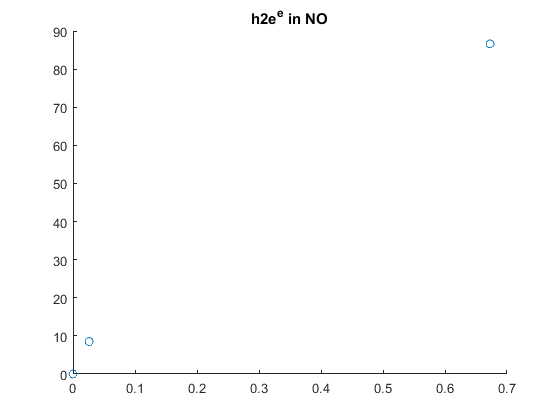


scatter(h2eevno,ssno)
title('h2e^e in NO')

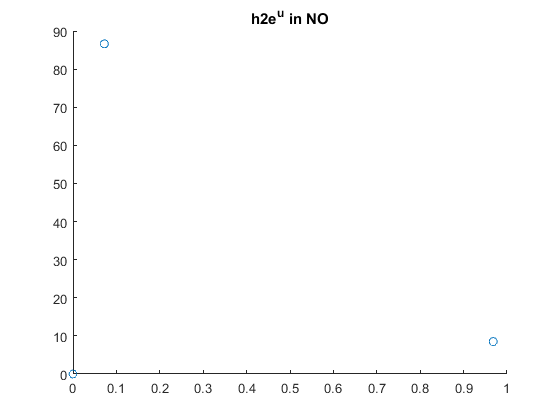


scatter(h2euvno,ssno)
title('h2e^u in NO')

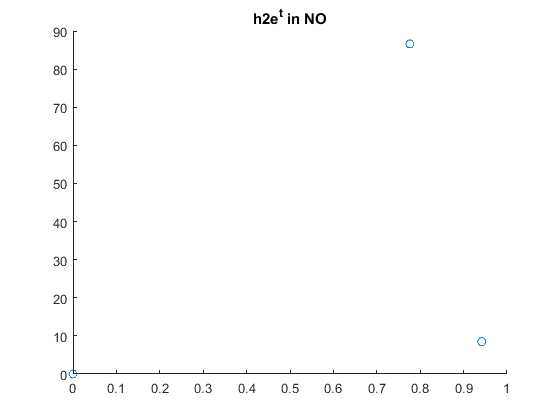


scatter(h2etvno,ssno)
title('h2e^t in NO')

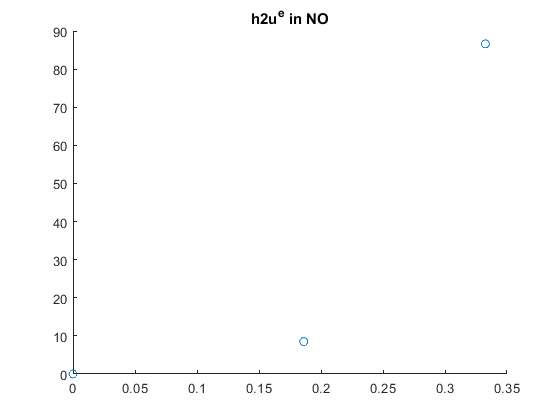


scatter(h2uevno,ssno)
title('h2u^e in NO')

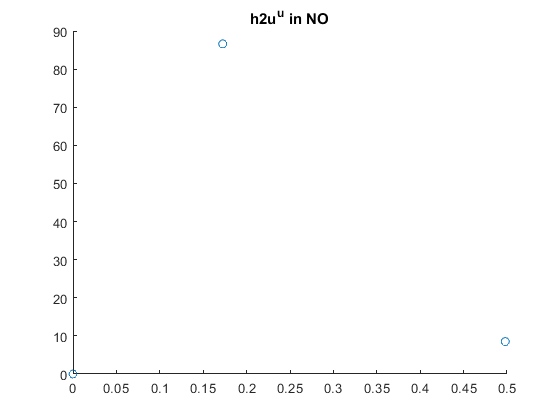


scatter(h2uuvno,ssno)
title('h2u^u in NO')

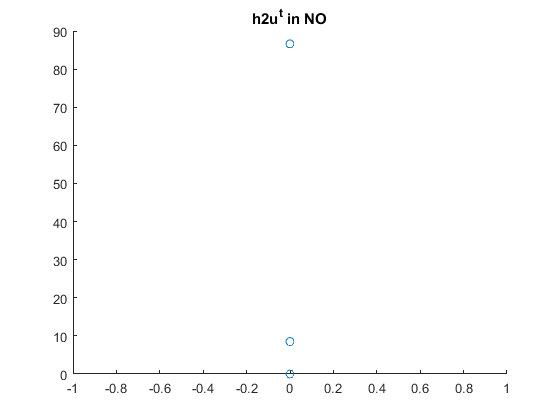


scatter(h2utvno,ssno)
title('h2u^t in NO')

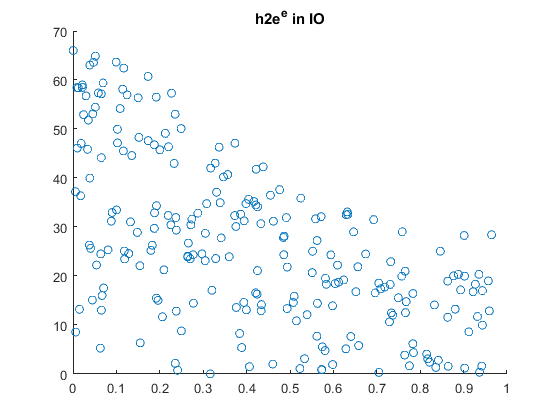



scatter(h2eevio,ssio)
title('h2e^e in IO')

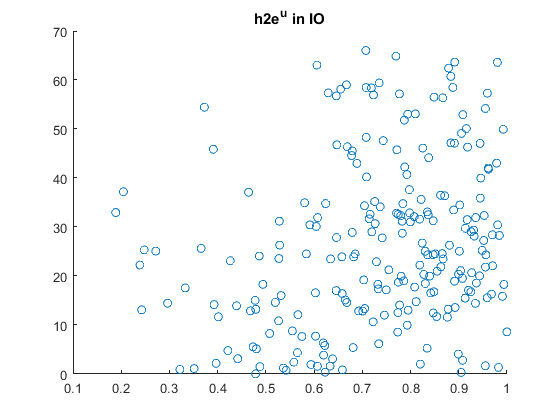


scatter(h2euvio,ssio)
title('h2e^u in IO')

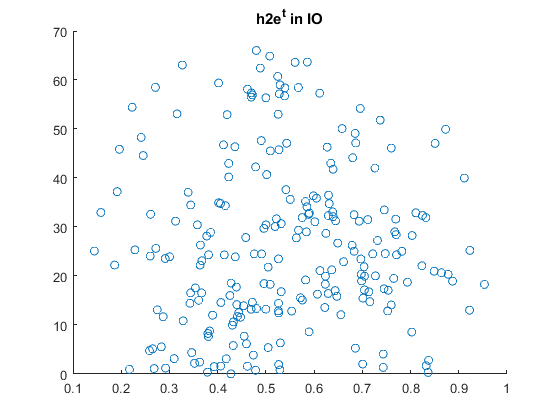


scatter(h2etvio,ssio)
title('h2e^t in IO')

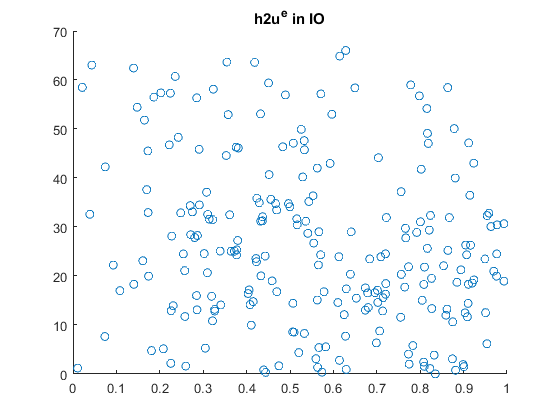


scatter(h2uevio,ssio)
title('h2u^e in IO')

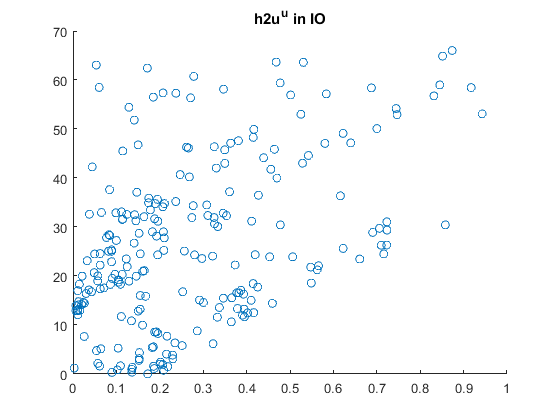


scatter(h2uuvio,ssio)
title('h2u^u in IO')

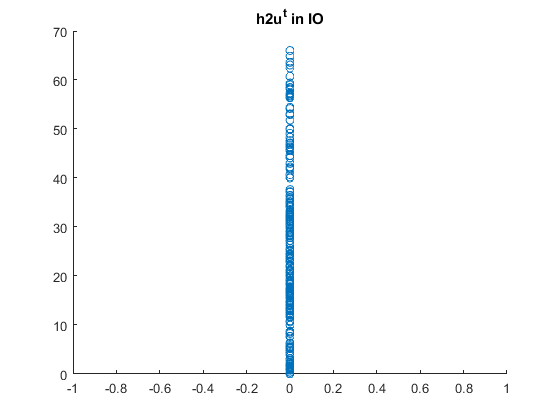


scatter(h2utvio,ssio)
title('h2u^t in IO')